clear vars;
edges = importdata("get_edges_output.txt");

edgesSplit = split(edges);
start_edges = edgesSplit(:,1);
end_edges = edgesSplit(:,2);

unique1 = unique(start_edges, 'stable');
unique2 = unique(end_edges, 'stable');
allUnique = unique(cat(1, unique1, unique2), 'stable');

adjMatrix = cell(length(allUnique) + 1);
al = length(adjMatrix);
adjMatrix(1, 2:al) = allUnique;
adjMatrix(2:al, 1) = allUnique

adjMatrix = 335×335 cell array
    {0×0 double             }    {'Annotations'}    {'BootstrapMethod'}    {'Constant'}    {'ConstantFieldref'}    {'ConstantInvokeDynamic'}    {'ConstantMethodType'}    {'ConstantPackage'}    {'DescendingVisitor'}    {'EnumElementValue'}    {'FieldOrMethod'}    {'Signature'}    {'StackMapEntry'}    {'Utility' }    {'AASTORE' }    {'ANEWARRAY'}    {'ArithmeticInstruction'}    {'BALOAD'  }    {'BranchHandle'}    {'CASTORE' }    {'ClassGen'}    {'ConversionInstruction'}    {'D2L'     }    {'DCMPG'   }    {'DLOAD'   }    {'DRETURN' }    {'DUP2'    }    {'DUP_X2'  }    {'EnumElementValueGen'}    {'F2I'     }    {'FASTORE' }    {'FDIV'    }    {'FieldInstruction'}    {'FMUL'    }    {'FSTORE'  }    {'GOTO'    }    {'I2C'     }    {'I2S'     }    {'IASTORE' }    {'IFGE'    }    {'IFLT'    }    {'IF_ACMPEQ'}    {'IF_ICMPGT'}    {'IINC'    }    {'IMUL'    }    {'Instruction'}    {'InstructionConstants'}    {'InstructionList'}    {'INVOKEINTERFACE'}    {'IOR'     

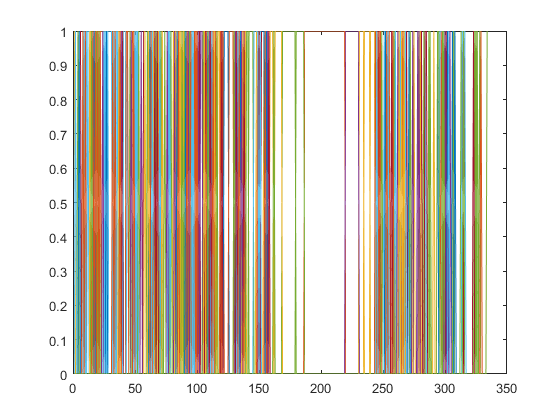


G = digraph(start_edges, end_edges);
A = adjacency(G);
B = full(A);

